# SISTEMAS DINÁMICOS

# TALLER 1

#### William Gómez, Juan Hernández, Juan Castro

#### Bogotá - 2023

#### *Resumen: *A partir del siguiente taller se evaluaron los temas de ecuaciones de estado y su respectiva solución tanto analítica como gráfica, además de sus correspondientes funciones de trasferencia, para lo cual se utilizo el siguiente circuito: 

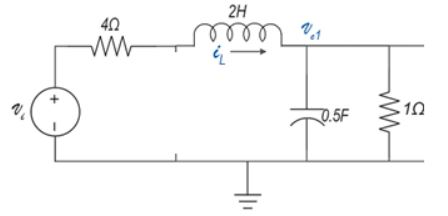

#### A partir de éste se determinaron las variables de estado, entradas, variables iniciales y sus respectivas salidas, para luego poder plantear su ecuación dinámmica. Ya con las ecuaciones planteadas, se prosiguió a realizar su forma matricial y a partir de acá implementando codigo de Matlab se obtuvieron sus soluciones. 

#### Las respuestas analíticas y grafica que se solicitaron fueron:

#### - Respuesta de entrada cero, con condiciones iniciales de i(0) =0.2A y Vc1(0) =0.2V. 

#### -Respuesta de entrada cero, siendo la entrada una señal paso de la forma Vi=10*1(t). 

#### -Respuesta completa. 

#### Para la obtención de las variables de transferencia se nos solicitó: 

#### - Función de transferencia para el circuito inicial, agregando su respectivo diagrama de polos y ceros. 

#### - Función de transferencia implementando, una señal paso. 

#### - Función de transferencia implementando la entrada Vi=2*sen(t). 

### DESARROLLO

#### I. Planteo y solución ecuación entrada – salida de circuitos eléctricos.

a) Plantear la ecuación diferencial de entrada – salida. La variable de salida deseada es el  voltaje sobre el condensador.

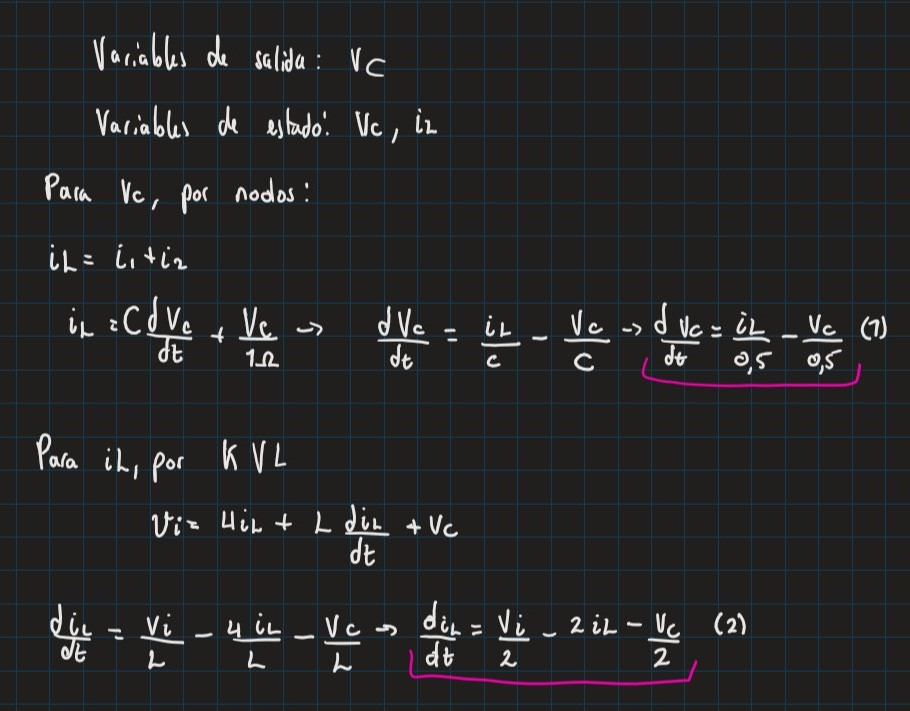

b)Si las condiciones iniciales son $X0=   \pmatrix{0.2[V] & 0.2[A]}$,obtener la respuesta  (para entrada cero) analítica y gráfica.

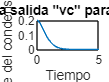

syms vc(t) il(t)

X0=[0.2 0.2];
C=0.5;
L=2;
r1=4;
r2=1;
vi=0;%Para entrada cero

Dvc= diff(vc,t)== (1/C)*(il -(vc/r2));
Dil= diff(il,t)== (1/L)*(vi- il*r1 - vc);
dX=[Dvc;Dil];

cond1 = vc(0)==0.2;
cond2 = il(0)==0.2;
cond=[cond1;cond2];

S= dsolve(dX, cond);
y= S.vc;

figure(1)
fplot(y)
xlim([0 5])
title('Respuesta salida "vc" para entrada cero')
xlabel('Tiempo')
ylabel('Voltaje del condensador [V]')

c)  Si la entrada es una señal paso de la forma $v_i =10*1\left(t\right)$, obtener la respuesta (para  estado cero) analítica y grafica.

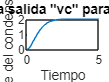

vi=10*heaviside(t);
Dvc= diff(vc,t)== (1/C)*(il -(vc/r2));
Dil= diff(il,t)== (1/L)*(vi- il*r1 - vc);
dX=[Dvc;Dil];

cond1 = vc(0)==0;
cond2 = il(0)==0;
cond=[cond1;cond2];

S2=dsolve(dX, cond);

y1=S2.vc;

figure(2)
fplot(y1)
xlim([0 5])
title('Respuesta salida "vc" para estado cero')
xlabel('Tiempo')
ylabel('Voltaje del condensador [V]')

d)Obtener la respuesta completa, analítica y gráfica.

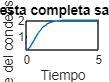

Y= y +y1;
figure(3)
fplot(Y)
xlim([0 5])
title('Respuesta completa salida "vc" ')
xlabel('Tiempo')
ylabel('Voltaje del condensador [V]')

#### II. Planteo y solución de modelo de estado de circuitos eléctricos. 

a)Para el mismo circuito plantear la ecuación dinámica de estado y la  ecuación de salida en forma matricial. Identificar las dimensiones de las matrices A,  B, C y D. La variable de salida de interés es el voltaje sobre el condensador.


$$\pmatrix{\dot{Vc} \cr \dot{Il}} = \pmatrix{-2 & 2 \cr -1/2 & -2}\pmatrix{Vc \cr Il} +  \pmatrix{0\cr 1/2 } Vi


$$



$$y = \pmatrix{1 &0}\pmatrix{Vc \cr Il} $$


b) Si las condiciones iniciales son$X0=   \pmatrix{0.2[V] & 0.2[A]}$, obtener la respuesta  (para entrada cero) analítica y gráfica.

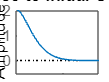

A=[-2 2; -1/2 -2];
B=[0; 1/2];

C=[1 0];
D=[0];

X0=[0.2 0.2];

sys = ss(A,B,C,D);
figure(4)
initial(sys,X0)

c) Si la entrada es una señal paso de la forma $v_i =10*1\left(t\right)$, obtener la respuesta (para  estado cero) analítica y grafica.

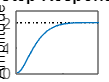

figure(5)

opt = stepDataOptions('StepAmplitude',10);
step(sys,opt)

d)Obtener la respuesta completa, analítica y grafica. 

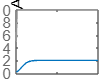

figure(6)
t=[0:0.1:9.9]';
u=10*heaviside(t);
lsim(sys,u,t,X0)

#### III. Obtención de la función de transferencia

a)Obtener la función de transferencia del circuito y graficar el diagrama de  polos y ceros. 

A=[-2 2; -1/2 -2];
B=[0; 1/2];
C=[1 0];
D=[0];

sys = ss(A,B,C,D);
H=tf(sys)

H =
 
        1
  -------------
  s^2 + 4 s + 5
 
Continuous-time transfer function.



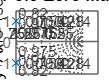

figure(7)
pzmap(H)
grid on

b) Si la entrada es una señal paso de la forma $v_i =10*1\left(t\right)$, obtener la respuesta (para  estado cero) grafica. 

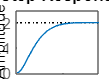

stepplot(H)

c)Repetir para una entrada$v_i =2*\sin \left(t\right)$

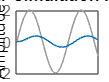

t=[0:0.1:9.9]';
vi=2*sin(t);
lsim(sys,vi,t)